# Smith predictor controller design  -  Advanced topic

Control is commonly implemented in discrete time. In order to be able to analyse behaviour in discrete time the user needs some understanding of discrete time models and how these can be handled in MATLAB. Often discrete models can be treated using z-transforms which MATLAB handles formally using tools in the control toolbox. The basic definition and usage of such discrete models is discussed in files ***discrete_models_and_usage.mlx  ***and ***discretization_and_bode.mlx***

The most commonly used PID controller design can be performed also in discrete case. Discrete PID controller design with pole cancellation technique is discussed in file ***discrete_models_and discrete_PID_controller_design.mlx***

If the process contains a large dead time (e.g. transport delay), with PID control the control system cannot be fast, as for ensuring a phase margin of about ${60}^{\circ }$,  the cut-off frequency is restricted to $\omega_c \approx \frac{1}{2\left(T_d +T_s \right)}$, where $T_d$ is the dead time and $T_s$ is the sampling time. (As it was discussed in file  ***discrete_models_and discrete_PID_controller_design.mlx ***sampling and zero order hold introduces extra delay into the control system.)

Referring to PID controller design in the frequency domain, at the cut-off frequency the open loop asymptotic Bode diagram should have a slope of -20dB/decade, and for calm transient behaviour generally a phase margin of about 60 degrees is required. This is reached if the cut-off frequency is set to the value given above. With a big dead time in the process the settling time will be high, its value is approximated by $\frac{3}{\omega_c }\le T_{\textrm{settling}} \le \frac{10}{\omega_c }$.

In the discrete case there are some controller design methods which may result in faster behaviour in the case of a big dead time. This can be an important practical issue. Such controller design methods include dead beat control, discussed in the file ***Dead_beat_controller_design_control101.mlx. ***Other approaches are Smith predictor controller design, Youla parameterisation and predictive control.

This file discusses Smith predictor controller design.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Ruth Bars, Budapest University of Technology and Economics                                               

with some input from J.A. Rossiter, University of Sheffield    

                                            

Reference: Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019.                     

## Table of contents

- Block diagram of the discrete control system

- The idea of Smith predictor controller design

- Numerical examples

## 1.Block diagram of the discrete control system

The block diagram of the discrete control system is given in Figure 1 below. The plant is continuous and here is characterised by its continuous time transfer function *G(s)*. Its output is sampled with sampling time $T_s$, and in its input a zero order hold is applied. The parts within the dotted box, including the digital/analog converter at the input and the analog/digital converter at the output of the plant, are described by the pulse transfer function $G\left(z\right)$. The controller is given by pulse transfer function *M(z)* and works in discrete time. 

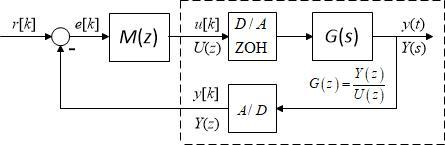

**Figure 1**: *Block diagram representation of a discrete control feedback loop*

The model *G(s)* of the plant is given in continuous time form, desribed by its transfer function. Sampling and holding introduces extra delay into the system, its value is typically between the half and the entire sampling time . The controller *M(z)* is discrete, its output values are calculated at the sampling instants and the zero order hold ZOH provides the continuous input at the input of the process. 

## 2.The idea of Smith predictor controller design

If the process contains a big dead time, with a PID controller the control system will be slow. O.J. Smith in 1957 suggested a control algorithm which behaves as if the dead time would have been located outside of the feedback loop (as shown in figure 2 below). So the controller $M_+$ is designed for the dead time free process, and thus the control system will be faster.

**Figure 2**: Smith predictor controller is designed for the system without dead time

For the equivalence of the two control circuits we can write:

$\frac{M\;P_{+\;} e^{-sT_d } }{1+M\;P_{+\;} e^{-sT_d } }=\frac{M_+ {\;P}_+ }{1+M_+ {\;P}_+ }\;e^{-sT_d }$ .

Hence the controller *M* is expressed as:

$M=\frac{M_+ }{1+M_+ {\;P}_+ \left(1-e^{-sT_d } \right)}$.

Of course practically the dead time is part of the process, it cannot be put outside of the control circuit, so *M* should be realised within the feedback control circuit, as given in the formula above.

As the dead time appears in the control algorithm, it is more difficult to realise the algorithm in continuous control systems. For discrete systems, the control algorithm is given by its pulse transfer function as:

$M\left(z\right)=\frac{M_+ \left(z\right)}{1+M_+ {\left(z\right)\;G}_+ \left(z\right)\left(1-z^{-d} \right)}$   (1)

where $G_+ \left(z\right)$ is the pulse transfer function of the delay free process and *d* is the discrete dead time, which is the ratio of the dead time and the sampling time.

**Remark**: While the changes in Figure 2 are solely conceptual, nevertheless these can be used to build a real control law *M(z)*. Readers will note that this control law includes a system model. Alternative block diagram representations of this controller realisation exist which emphasise how  this system model is a core part of the control law and can be used to produce undelayed predictions of expected behaviour; these alternative realisations are also easier to implement for continuous systems. Moreover, while not discussed here, this control law can be very sensitive to parameter uncertainty and thus some authors in recent times have suggested that it is often better, and easier, to use a simpler de-tuned controller with much lower bandwidth. 

The summary proposal then is:

- Design a compensator $M_+$ for the system without a delay.

- Use equation (1) to design the compensator for the delayed system.

## 3. Numerical examples

Let us consider the same examples discussed in the dead beat controller design file (***Dead_beat_controller_design_control101.mlx)***. In the delay free case, a PI or PID controller can be designed which ensures approximately a 60 degrees phase margin (of course a dead beat control algorithm could be also applied).

**Remark**:  *minreal.m* is used to cancel pole/zero pairs and thus simplify the designs. In the case of parameter uncertainty such cancellations will not be present.

### 3.1 Examples

#### Example 3.1

The transfer function of the plant is:

$G\left(s\right)=\frac{e^{-10s} }{1+5s}$; 

The sampling time is $T_s =2\ldotp 5$. The reference signal is a unit step. Design the Smith predictor controller, give its pulse transfer function and simulate the output and the control signal. 

disp('EXAMPLE 3.1: Design of Smith predictor controller')
s=zpk('s');
G=1/(1+5*s)       % Continuous Model without the delay
Ts=2.5;           % sampling time
z=zpk('z',Ts);
% The pulse transfer function without the delay
Gz=c2d(G,Ts);   %or alternatively Gz=c2d(G,Ts,'zoh'), discrete model
% Poles, zeros and gain of the process
[zer,pol,kd]=zpkdata(Gz,'v');
disp('The pulse transfer function with the delay')
Gz1=Gz*z^-4     % Discrete model with the delay


Compensator design for the undelayed system to achieve a 60 degree phase margin uses the pole cancellation method ([`discrete_models_and_discrete_PID_controller_design.m`](matlab: discrete_models_and_discrete_PID_controller_design)`)`.

disp('Design PI controller for the delay free process with pole cancellation method')
Mplus=(z-pol)/(z-1);   % PI structure with desired zeero
Lz=minreal(Mplus*Gz,0.001);
w=logspace(-1,0,200);
[mag,phase]=bode(Lz,w);
ki=margin(mag,phase-60,w);   % choose gain of the controller to achieve 60 degree PM
Mplus1=ki*Mplus

Having formulated the controller for the undelayed case, the next step is to form the controller for the delayed system using equation (1) and do some closed-loop simulation and evaluation.

disp('The Smith controller')
M=Mplus1/(1+Mplus1*Gz*(1-z^-4));
M=minreal(M,0.001)
L=minreal(M*Gz1,0.001);
T=minreal(L/(1+L),0.001); % closed-loop transfer functions
U=minreal(M/(1+L),0.001)

% Simulations
tfinal=40; %0:2.5:30;
step(T,tfinal),grid
title('The closed-loop discrete output signal')
xlabel('Time (sec)')
step(U,tfinal)
title('The closed-loop discrete control signal')
xlabel('Time (sec)')
ylim([0,2.6])

It is seen that the output is settled soon after the dead time and, because a pole cancellation design technique has been used, the output settles immediately at the target value.

#### Example 3.2

The transfer function of the plant is:

$G\left(s\right)=\frac{e^{-12s} }{\left(1+4s\right)\left(1+10s\right)}$; 

The sampling time is $T_s =2$. The reference signal is a unit step. Design a Smith predictor controller.  For the delay free process design a PID controller for about 60 degrees phase margin. Give the pulse transfer function of the PID controller and of the Smith predictor controller. Simulate the output and the control signal. 

disp('EXAMPLE 3.2: Design of a Smith predictor controller')
s=zpk('s');
G=1/((1+4*s)*(1+10*s))
Ts=2;          %sampling time
z=zpk('z',Ts);
% The pulse transfer function of the process with no delay
Gz=c2d(G,Ts);   %or alternatively Gz=c2d(G,Ts,'zoh'), discrete model
disp('The pulse transfer function of the delayed process')
Gz1=Gz*z^-6

Compensator design for the undelayed system to achieve a 60 degree phase margin uses the pole cancellation method ([`discrete_models_and_discrete_PID_controller_design.m`](matlab: discrete_models_and_discrete_PID_controller_design)`)`.

disp('PID controller for the delay free process with 60 degrees phase margin')
[zer,pol,k]=zpkdata(Gz,'v');
Mplus=(z-pol(1))*(z-pol(2))/((z-1)*z);
Lplus=minreal(Mplus*Gz,0.001);
[mag,phase,w]=bode(Lplus);
k=margin(mag,phase-60,w)
Mplus1=k*Mplus

Having formulated the controller for the undelayed case, the next step is to form the controller for the delayed system using equation (1) and do some closed-loop simulation and evaluation.

% Closed-loop transfer functions delay free case
Lplus1=k*Lplus;
T=Lplus1/(1+Lplus1);
T=minreal(T,0.001);
U=Mplus1/(1+Lplus1);

% Closed-loop transfer functions with delay
Mz=Mplus1/(1+Mplus1*Gz*(1-z^-6));
Mz=minreal(Mz,0.001)
Lsm=minreal(Mz*Gz1,0.001);
Tsm=minreal(Lsm/(1+Lsm),0.001);
Usm = minreal(Mz/(1+Lsm),0.001);


% Simulations comparing behaviour with and without a delay
tfinal=30; %0:2:30
step(T,Tsm,tfinal),grid
title('Step responses of the Smith predictor control system')
xlabel('Time (sec)')
legend('with no delay', 'with delay','Location','Southeast')
step(U,Usm,tfinal),grid
disp('The control signal')
legend('no delay', 'with delay')
title('The control signal of the Smith predictor control system')

It is seen that the control signal is the same as in the case of the delay free process and the output of the control system is just shifted by the dead time related to the response of the delay free control system.

### 3.2 Inter sample behaviour

In order to explore the intersample behaviour it is convenient to run the simulation using simulink and enter the blocks of Figure 1 explicitly. The corresponding simulink diagram is shown in Figure 2. Readers can open and edit this file for their own purposes. 

      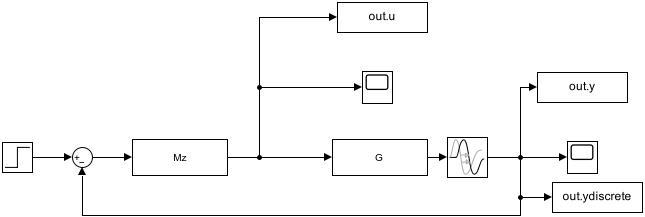

**Figure 2**: Simulink diagram of a discretised control loop, inlcuding the ZOH (***simulink_deadtime_control101.slx***)

% to open simulink file 
% open simulink_deadtime_control101.slx

The *Mz* discrete and the *G *continuous transfer function blocks are read directly from the workspace. It is not necessary to put a ZOH element between them, as this is embedded within *Mz* automatically within the MATLAB environment, that is, the output of this block is held automatically. Code for running this simulink file is given next. It is important to define in the workspace the variables which the file will be using. 

**It is assumed the relevant data Mz and G has been generated in the sections above! If needs be, run those subsections first.**

% Run the Simulink Simulation
Greal=G;      % real process same as model
deadtime=12;  % in seconds not samples
endtime=50;
tplot = 0.2;  % Sample rate for collecting data from simulink
Data= sim('simulink_deadtime_control101.slx');
y=Data.y.signals.values;
u=Data.u.signals.values;
t = Data.u.time;
ydiscrete=Data.ydiscrete.signals.values;
tdiscrete = Data.ydiscrete.time;

% Plotting
plot(t,y,'b',tdiscrete,ydiscrete,'ro'),grid
legend('Continuous values','Sampled values','Location','Southeast')
xlabel('Time (sec)')
title('Closed-loop step response of the smith predictor control system')
stairs(t,u),grid  % useful function to avoid MATLAB interpolating between different values
title('Control signal')
xlabel('Time (sec)')

It is seen that the behaviour is calm and notably, there are no intersampling oscillations.

### 3.3 Impact of parameter uncertainty

Let us analyse the behaviour of the control system if there is mismatch in the model parameters or dead time. The controller has been calculated for a dead time 12 sec. The code below uses an actual dead time of 12.5 sec. You can also embed other parameter errors into the simulation by redefining the real system *Greal* at this point while generating *Mz* using the code in the earlier sections with the model *G*.

This section assumes sections 3.1 and 3.2 are run first to define core parameters.

%Simulation
Greal = 1/((1+4*s)*(1+11*s));
deadtime = 12.5;  % in seconds not samples
endtime=100;
Data= sim('simulink_deadtime_control101.slx');
y2=Data.y.signals.values;
t2 = Data.u.time;
ydiscrete2=Data.ydiscrete.signals.values;
tdiscrete2 = Data.ydiscrete.time;

% Plotting
plot(t2,y2,'b',tdiscrete2,ydiscrete2,'ro',t,y,'g'),grid
legend('Continuous values','Sampled values','With no uncertainty','Location','Southeast')
xlabel('Time (sec)')
title('Step response with modelling parameter errors')

It is seen that the algorithm tolerates this uncertainty but the behaviour has changed notably from when there was no parameter uncertainty.

Reference: O. J. Smith, *Closer control of loops with dead time*, Chemical Engineering Progress, 53 (1957), pp. 217–219